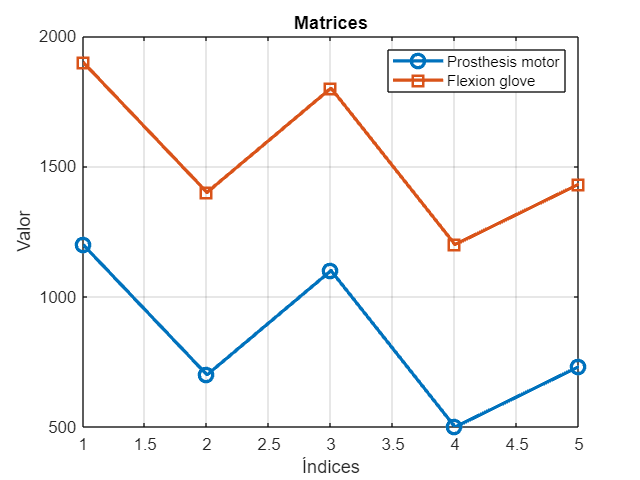

% Se toma la misma acción, solo difieren en distancia
prosthesis_distance = [700, 1100, 500, 732];
glove_distance = [1400, 1800, 1200, 1432];
prosthesis_direction = [1200, 700, 1100, 500, 732];
glove_direction = [1900, 1400, 1800, 1200, 1432];
% Crear un vector de índices para los datos
indices = 1:length(prosthesis_direction);
% Graficar los puntos unidos de prosthesis_direction
plot(indices, prosthesis_direction, '-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on; % Mantener el gráfico actual para agregar más datos
% Graficar los puntos unidos de glove_direction
plot(indices, glove_direction, '-s', 'LineWidth', 2, 'MarkerSize', 8);
% Añadir etiquetas y título al gráfico
xlabel('Índices');
ylabel('Valor');
title('Matrices');
% Agregar leyenda
legend('Prosthesis motor', 'Flexion glove');
% Mostrar la cuadrícula
grid on;
% Soltar el gráfico actual
hold off;

% Inicializar la sumatoria de diferencias
sumatoria_diferencias = 0;
% Comparar los valores de 1 en 1 y obtener la sumatoria de las diferencias
for i = 1:4
    diferencia = abs(prosthesis_distance(i) - glove_distance(i));
    sumatoria_diferencias = sumatoria_diferencias + diferencia;
    fprintf('La diferencia %d es: %s\n', i, num2str(diferencia));
end

La diferencia 1 es: 700
La diferencia 2 es: 700
La diferencia 3 es: 700
La diferencia 4 es: 700


% Mostrar el resultado global
disp(['La sumatoria global de las diferencias es:', num2str(-1*sumatoria_diferencias)]);

La sumatoria global de las diferencias es:-2800


%% Calcular las pendientes de la primera matriz
pendiente_matriz1 = diff(prosthesis_direction);
disp(['Pendiente 1: ', num2str(pendiente_matriz1)]);

Pendiente 1: -500  400 -600  232


% Calcular las pendientes de la segunda matriz
pendiente_matriz2 = diff(glove_direction);
disp(['Pendiente 2: ', num2str(pendiente_matriz2)]);

Pendiente 2: -500  400 -600  232


% Calcular la diferencia entre las pendientes
diferencia_pendientes = pendiente_matriz1 - pendiente_matriz2;
disp(['Diferencia entre las pendientes: ', num2str(diferencia_pendientes)]);

Diferencia entre las pendientes: 0  0  0  0


% Modificar la diferencia según los criterios
for i = 1:length(diferencia_pendientes)
    % Casos de valor -6
    if (pendiente_matriz1(i) > 0 && pendiente_matriz2(i) < 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) > 0)
        diferencia_pendientes(i) = -6;
    % Casos de valor -4
    elseif(pendiente_matriz1(i) > 0 && pendiente_matriz2(i) == 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) == 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) > 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) < 0)
        diferencia_pendientes(i) = -4;    
    % Casos de valor 2
    elseif (sumatoria_diferencias > 100 && sumatoria_diferencias/10 <= 200) && ((pendiente_matriz1(i) > 0 && pendiente_matriz2(i) > 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) < 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) == 0))
        diferencia_pendientes(i) = 2;    
    % Casos de valor 4
    elseif (sumatoria_diferencias > 0 && sumatoria_diferencias/10 <= 100) && ((pendiente_matriz1(i) > 0 && pendiente_matriz2(i) > 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) < 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) == 0))
        diferencia_pendientes(i) = 4;    
    % Casos de valor 6
    elseif (sumatoria_diferencias == 0) && ((pendiente_matriz1(i) > 0 && pendiente_matriz2(i) > 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) < 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) == 0))
        diferencia_pendientes(i) = 6;
    else
        diferencia_pendientes(i) = -2;
    end
end
% Mostrar la diferencia modificada
disp(['Diferencia entre las pendientes: ', num2str(diferencia_pendientes)]);

Diferencia entre las pendientes: -2 -2 -2 -2


% Mostrar la recompensa
reward = sum(diferencia_pendientes);
disp(['LA RECOMPENSA ES: ', num2str(reward)]);

LA RECOMPENSA ES: -8
